# MULTIBODY SOLUTION - EXAM 09/07/2025

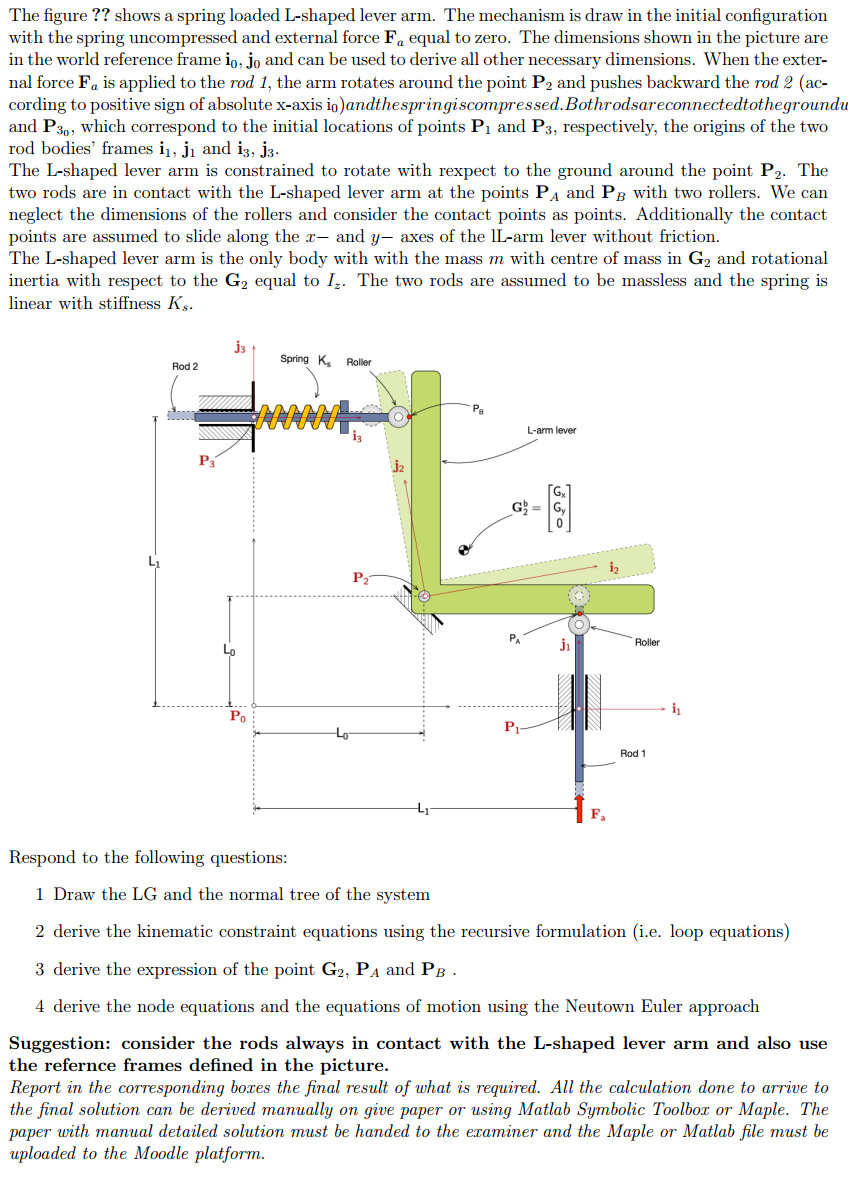

*Both rods are connected to the ground using prismatic joints in *$P_{1_0}$* and *$P_{3_0}$

**!! NOTE**: rollers are **CAM JOINTS**, modeled as a combination of a **PRISMATIC + REVOLUTE JOINT**

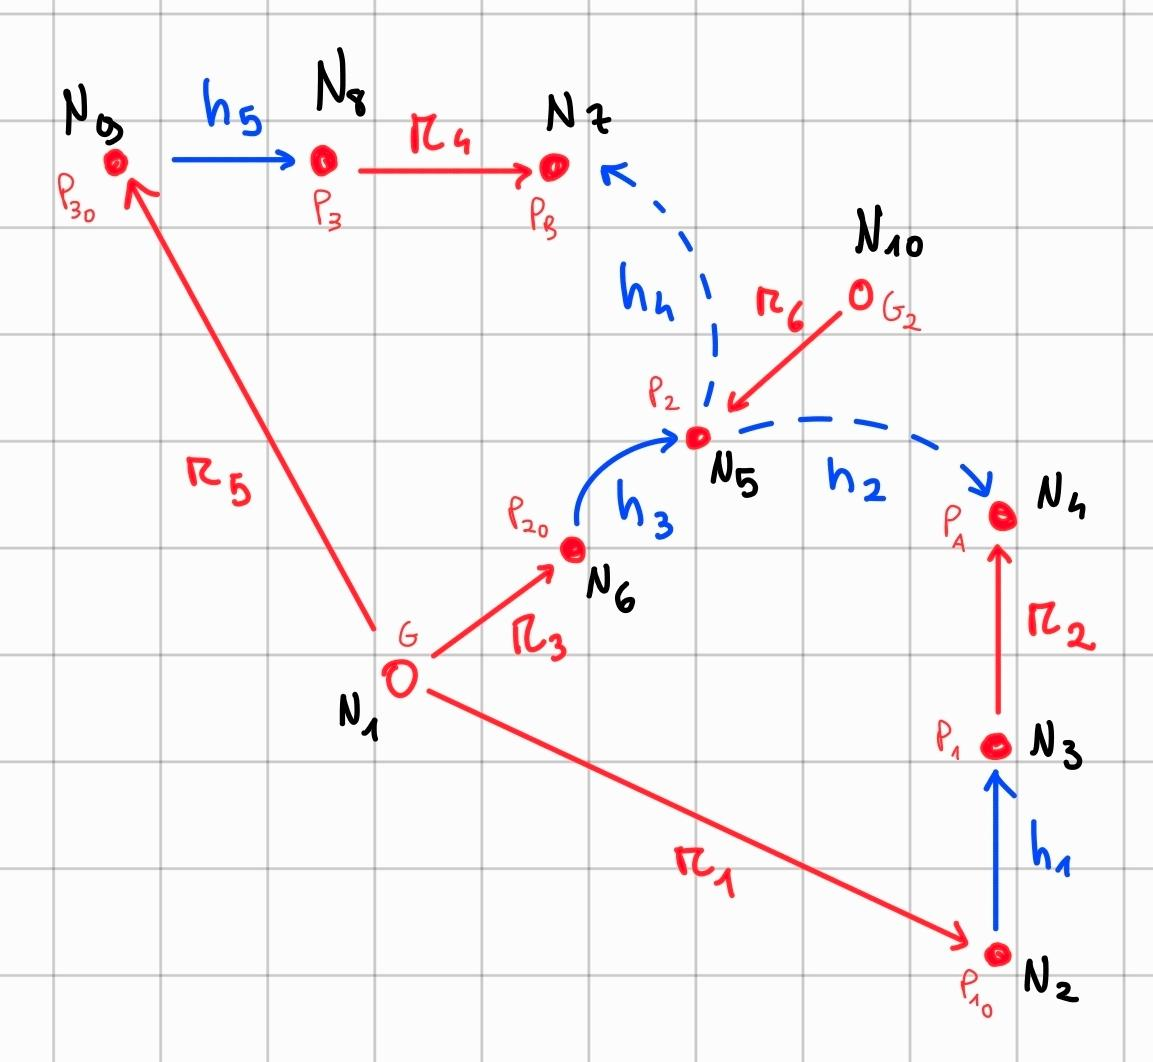

### 0) Sytem data and definition

clear;
clc;
close all;
syms t
addpath('MBLibs\');

System unknowns and parameters

% Unknowns
syms theta_1(t) s_1(t) s_2(t)
% Given parameters
syms L_0 L_1 G_x G_y

### 1) Kinematic equations

#### Bodies

L-shaped lever arm

R1 = rotate3('Z', theta_1(t));
b = [G_x; G_y; 0];

#### Joints

J1 right prismatic

j1 = [0; 1; 0];
h1 = s_1(t)*j1

$$h1 = \left(\begin{array}{c} 0\\ s_{1}\left(t\right)\\ 0 \end{array}\right)$$

J2 right cam

syms theta_J2(t)
RJ2 = rotate3('Z', theta_J2(t));
h2 = RJ2 * (s_1(t)*j1)

$$h2 = \left(\begin{array}{c} -\sin\left(\theta_{\mathrm{J2}}\left(t\right)\right)\,s_{1}\left(t\right)\\ \cos\left(\theta_{\mathrm{J2}}\left(t\right)\right)\,s_{1}\left(t\right)\\ 0 \end{array}\right)$$

J3 revolute

syms theta_J3(t)
RJ3 = rotate3('Z', theta_J3(t))

$$RJ3 = \left(\begin{array}{ccc} \cos\left(\theta_{\mathrm{J3}}\left(t\right)\right) & -\sin\left(\theta_{\mathrm{J3}}\left(t\right)\right) & 0\\ \sin\left(\theta_{\mathrm{J3}}\left(t\right)\right) & \cos\left(\theta_{\mathrm{J3}}\left(t\right)\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

h3 = zeros(3,1)

h3 =      0
     0
     0


J4 left cam

syms theta_J4(t)
i3 = [1; 0; 0];
RJ4 = rotate3('Z', theta_J4(t));
h4 = RJ4 * (s_2(t)*i3)

$$h4 = \left(\begin{array}{c} \cos\left(\theta_{\mathrm{J4}}\left(t\right)\right)\,s_{2}\left(t\right)\\ \sin\left(\theta_{\mathrm{J4}}\left(t\right)\right)\,s_{2}\left(t\right)\\ 0 \end{array}\right)$$

J5 left prismatic

h5 = s_2(t)*i3

$$h5 = \left(\begin{array}{c} s_{2}\left(t\right)\\ 0\\ 0 \end{array}\right)$$

#### Arm-links

% With simple translations
% r1
r1 = [L_1; 0; 0]

$$r1 = \left(\begin{array}{c} L_{1}\\ 0\\ 0 \end{array}\right)$$

% r3
r3 = [L_0; L_0; 0]

$$r3 = \left(\begin{array}{c} L_{0}\\ L_{0}\\ 0 \end{array}\right)$$

% r5
r5 = [0; L_1; 0]

$$r5 = \left(\begin{array}{c} 0\\ L_{1}\\ 0 \end{array}\right)$$


% Other arm-links (follow the kinematic chain to project to global frame)
% r2
ra2 = [0; L_0; 0];
r2 = RJ3 * RJ2 * ra2

$$r2 = \left(\begin{array}{c} -L_{0}\,\left(\cos\left(\theta_{\mathrm{J2}}\left(t\right)\right)\,\sin\left(\theta_{\mathrm{J3}}\left(t\right)\right)+\cos\left(\theta_{\mathrm{J3}}\left(t\right)\right)\,\sin\left(\theta_{\mathrm{J2}}\left(t\right)\right)\right)\\ -L_{0}\,\left(\sin\left(\theta_{\mathrm{J2}}\left(t\right)\right)\,\sin\left(\theta_{\mathrm{J3}}\left(t\right)\right)-\cos\left(\theta_{\mathrm{J2}}\left(t\right)\right)\,\cos\left(\theta_{\mathrm{J3}}\left(t\right)\right)\right)\\ 0 \end{array}\right)$$

% r4
ra4 = [L_0; 0; 0];
r4 = RJ3 * RJ4 * ra4

$$r4 = \left(\begin{array}{c} -L_{0}\,\left(\sin\left(\theta_{\mathrm{J3}}\left(t\right)\right)\,\sin\left(\theta_{\mathrm{J4}}\left(t\right)\right)-\cos\left(\theta_{\mathrm{J3}}\left(t\right)\right)\,\cos\left(\theta_{\mathrm{J4}}\left(t\right)\right)\right)\\ L_{0}\,\left(\cos\left(\theta_{\mathrm{J3}}\left(t\right)\right)\,\sin\left(\theta_{\mathrm{J4}}\left(t\right)\right)+\cos\left(\theta_{\mathrm{J4}}\left(t\right)\right)\,\sin\left(\theta_{\mathrm{J3}}\left(t\right)\right)\right)\\ 0 \end{array}\right)$$

% r6
ra6 = [-G_x; -G_y; 0];
r6 = RJ3*ra6

$$r6 = \left(\begin{array}{c} G_{y}\,\sin\left(\theta_{\mathrm{J3}}\left(t\right)\right)-G_{x}\,\cos\left(\theta_{\mathrm{J3}}\left(t\right)\right)\\ -G_{x}\,\sin\left(\theta_{\mathrm{J3}}\left(t\right)\right)-G_{y}\,\cos\left(\theta_{\mathrm{J3}}\left(t\right)\right)\\ 0 \end{array}\right)$$

### 2) Loop equations

#### **R-Tree**

Phi_thetaJ2 = theta_J2 == -theta_1;
Phi_thetaJ4 = theta_J4 == -theta_1;
Phi_thetaJ3 = theta_J3 == theta_1;
Phi_thetaJi = [Phi_thetaJ2; Phi_thetaJ4; Phi_thetaJ3]

$$Phi\_thetaJi(t) = \left(\begin{array}{c} \theta_{\mathrm{J2}}\left(t\right)=-\theta_{1}\left(t\right)\\ \theta_{\mathrm{J4}}\left(t\right)=-\theta_{1}\left(t\right)\\ \theta_{\mathrm{J3}}\left(t\right)=\theta_{1}\left(t\right) \end{array}\right)$$

#### T-Tree

First loop (solve for cut-joint J2 edge)

eq_cut1 = h2 == r1 + h1 + r2 - h3 - r3

$$eq\_cut1 = \left(\begin{array}{c} -\sin\left(\theta_{\mathrm{J2}}\left(t\right)\right)\,s_{1}\left(t\right)=L_{1}-L_{0}-L_{0}\,\left(\cos\left(\theta_{\mathrm{J2}}\left(t\right)\right)\,\sin\left(\theta_{\mathrm{J3}}\left(t\right)\right)+\cos\left(\theta_{\mathrm{J3}}\left(t\right)\right)\,\sin\left(\theta_{\mathrm{J2}}\left(t\right)\right)\right)\\ \cos\left(\theta_{\mathrm{J2}}\left(t\right)\right)\,s_{1}\left(t\right)=s_{1}\left(t\right)-L_{0}-L_{0}\,\left(\sin\left(\theta_{\mathrm{J2}}\left(t\right)\right)\,\sin\left(\theta_{\mathrm{J3}}\left(t\right)\right)-\cos\left(\theta_{\mathrm{J2}}\left(t\right)\right)\,\cos\left(\theta_{\mathrm{J3}}\left(t\right)\right)\right)\\ 0=0 \end{array}\right)$$

Project onto reaction space of the joint J2

ij2 = get_unit_vector3('X', RJ2);
tmp = simplify(expand(eq_cut1.'*ij2));
tmp = subs(tmp, lhs(Phi_thetaJi), rhs(Phi_thetaJi));
Phi_J2 = subs(tmp, lhs(Phi_thetaJi), rhs(Phi_thetaJi))

$$Phi\_J2 = L_{0}\,\left(\sin\left(\theta_{1}\left(t\right)\right)+\sqrt{2}\,\sin\left(\frac{\pi }{4}-\theta_{1}\left(t\right)\right)\right)=L_{1}\,\cos\left(\theta_{1}\left(t\right)\right)-\sin\left(\theta_{1}\left(t\right)\right)\,s_{1}\left(t\right)$$

Second loop (solve for cut-joint J4 edge)

eq_cut2 = h4 == r5 + h5 + r4 - h3 - r3

$$eq\_cut2 = \left(\begin{array}{c} \cos\left(\theta_{\mathrm{J4}}\left(t\right)\right)\,s_{2}\left(t\right)=s_{2}\left(t\right)-L_{0}-L_{0}\,\left(\sin\left(\theta_{\mathrm{J3}}\left(t\right)\right)\,\sin\left(\theta_{\mathrm{J4}}\left(t\right)\right)-\cos\left(\theta_{\mathrm{J3}}\left(t\right)\right)\,\cos\left(\theta_{\mathrm{J4}}\left(t\right)\right)\right)\\ \sin\left(\theta_{\mathrm{J4}}\left(t\right)\right)\,s_{2}\left(t\right)=L_{1}-L_{0}+L_{0}\,\left(\cos\left(\theta_{\mathrm{J3}}\left(t\right)\right)\,\sin\left(\theta_{\mathrm{J4}}\left(t\right)\right)+\cos\left(\theta_{\mathrm{J4}}\left(t\right)\right)\,\sin\left(\theta_{\mathrm{J3}}\left(t\right)\right)\right)\\ 0=0 \end{array}\right)$$

Project onto reaction space of J4

jj4 = get_unit_vector3('Y', RJ4);
tmp = simplify(expand(eq_cut2.'*jj4));
tmp = subs(tmp, lhs(Phi_thetaJi), rhs(Phi_thetaJi));
Phi_J4 = subs(tmp, lhs(Phi_thetaJi), rhs(Phi_thetaJi))

$$Phi\_J4 = L_{1}\,\cos\left(\theta_{1}\left(t\right)\right)=L_{0}\,\cos\left(\theta_{1}\left(t\right)\right)-\sin\left(\theta_{1}\left(t\right)\right)\,s_{2}\left(t\right)$$

### CoM Kinematics

In this case the two rods are considered massless, so only express position, acceleration and angular velocity of the CoM of the lever arm (G2 in the diagrams)

G2 = subs(r3+h3-r6, lhs(Phi_thetaJi), rhs(Phi_thetaJi))

$$G2 = \left(\begin{array}{c} L_{0}-G_{y}\,\sin\left(\theta_{1}\left(t\right)\right)+G_{x}\,\cos\left(\theta_{1}\left(t\right)\right)\\ L_{0}+G_{x}\,\sin\left(\theta_{1}\left(t\right)\right)+G_{y}\,\cos\left(\theta_{1}\left(t\right)\right)\\ 0 \end{array}\right)$$

VG2 = diff(G2, t);
% Acceleration
AG2 = diff(VG2,t);
% Reduce to first order derivative
syms theta_1dot(t)
AG2 = subs(AG2, diff(theta_1(t),t), theta_1dot(t))

$$AG2 = \left(\begin{array}{c} G_{y}\,\sin\left(\theta_{1}\left(t\right)\right)\,{\theta_{\mathrm{1dot}}\left(t\right)}^{2}-G_{x}\,\cos\left(\theta_{1}\left(t\right)\right)\,{\theta_{\mathrm{1dot}}\left(t\right)}^{2}-G_{y}\,\cos\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{\mathrm{1dot}}\left(t\right)-G_{x}\,\sin\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{\mathrm{1dot}}\left(t\right)\\ G_{x}\,\cos\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{\mathrm{1dot}}\left(t\right)-G_{x}\,\sin\left(\theta_{1}\left(t\right)\right)\,{\theta_{\mathrm{1dot}}\left(t\right)}^{2}-G_{y}\,\cos\left(\theta_{1}\left(t\right)\right)\,{\theta_{\mathrm{1dot}}\left(t\right)}^{2}-G_{y}\,\sin\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{\mathrm{1dot}}\left(t\right)\\ 0 \end{array}\right)$$

% Angular velocity
tmp = subs(simplify(RJ3.'*diff(RJ3,t)), lhs(Phi_thetaJi), rhs(Phi_thetaJi)); % Skew symm matrix
ang_vel1 = subs([tmp(3,2); tmp(1,3); tmp(2,1)], diff(theta_1(t),t), theta_1dot(t))

$$ang\_vel1 = \left(\begin{array}{c} 0\\ 0\\ \theta_{\mathrm{1dot}}\left(t\right) \end{array}\right)$$

Define positions of P_A, P_B, P_2 in World frame (absolute coordinates) and their distances to CoM (G2) in body frame

% P_A
P_A = r1 + h1 + r2;
% Distance vector between P_A and G2
d_G2PA_W = P_A - G2;                % in world coordinates
d_G2PA = subs(inv_rot_mat(R1) * d_G2PA_W, lhs(Phi_thetaJi), rhs(Phi_thetaJi));
d_G2PA = simplify(subs(d_G2PA, lhs(Phi_thetaJi), rhs(Phi_thetaJi))) % distance projected in body frame

$$d\_G2PA = \left(\begin{array}{c} \sin\left(\theta_{1}\left(t\right)\right)\,s_{1}\left(t\right)-G_{x}-L_{0}\,\cos\left(\theta_{1}\left(t\right)\right)+L_{1}\,\cos\left(\theta_{1}\left(t\right)\right)\\ L_{0}\,\sin\left(\theta_{1}\left(t\right)\right)-G_{y}-L_{1}\,\sin\left(\theta_{1}\left(t\right)\right)+\cos\left(\theta_{1}\left(t\right)\right)\,s_{1}\left(t\right)\\ 0 \end{array}\right)$$


% P_B
P_B = r5 + h5 + r4;
% Distance vector between P_B and G2
d_G2PB_W = P_B - G2;                % in world coordinates
d_G2PB = subs(inv_rot_mat(R1) * d_G2PB_W, lhs(Phi_thetaJi), rhs(Phi_thetaJi));
d_G2PB = simplify(subs(d_G2PB, lhs(Phi_thetaJi), rhs(Phi_thetaJi))) % distance projected in body frame

$$d\_G2PB = \left(\begin{array}{c} L_{1}\,\sin\left(\theta_{1}\left(t\right)\right)-L_{0}\,\sin\left(\theta_{1}\left(t\right)\right)-G_{x}+\cos\left(\theta_{1}\left(t\right)\right)\,s_{2}\left(t\right)\\ L_{1}\,\cos\left(\theta_{1}\left(t\right)\right)-\sin\left(\theta_{1}\left(t\right)\right)\,s_{2}\left(t\right)-L_{0}\,\cos\left(\theta_{1}\left(t\right)\right)-G_{y}\\ 0 \end{array}\right)$$


% P_2
P_2 = r3 + h3;
% Distance vector between P_2 and G2
d_G2P2_W = P_2 - G2;                % in world coordinates
d_G2P2 = subs(inv_rot_mat(R1) * d_G2P2_W, lhs(Phi_thetaJi), rhs(Phi_thetaJi));
d_G2P2 = simplify(subs(d_G2P2, lhs(Phi_thetaJi), rhs(Phi_thetaJi))) % distance projected in body frame

$$d\_G2P2 = \left(\begin{array}{c} -G_{x}\\ -G_{y}\\ 0 \end{array}\right)$$

### 3) Equations of Dynamics

#### Constitutive eq. of Bodies

B1

syms m Iz1 Fb_x(t) Fb_y(t) Tb_z(t)
Fb = [Fb_x(t); Fb_y(t); 0];
Tb = [0; 0; Tb_z(t)];
% Newton-Euler generic equations
eqn_N_B = m*AG2 == Fb

$$eqn\_N\_B = \left(\begin{array}{c} -m\,\left(G_{x}\,\cos\left(\theta_{1}\left(t\right)\right)\,{\theta_{\mathrm{1dot}}\left(t\right)}^{2}-G_{y}\,\sin\left(\theta_{1}\left(t\right)\right)\,{\theta_{\mathrm{1dot}}\left(t\right)}^{2}+G_{y}\,\cos\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{\mathrm{1dot}}\left(t\right)+G_{x}\,\sin\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{\mathrm{1dot}}\left(t\right)\right)={\mathrm{Fb}}_{x}\left(t\right)\\ -m\,\left(G_{y}\,\cos\left(\theta_{1}\left(t\right)\right)\,{\theta_{\mathrm{1dot}}\left(t\right)}^{2}+G_{x}\,\sin\left(\theta_{1}\left(t\right)\right)\,{\theta_{\mathrm{1dot}}\left(t\right)}^{2}-G_{x}\,\cos\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{\mathrm{1dot}}\left(t\right)+G_{y}\,\sin\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{\mathrm{1dot}}\left(t\right)\right)={\mathrm{Fb}}_{y}\left(t\right)\\ 0=0 \end{array}\right)$$

eqn_E_B = Iz1*ang_vel1 == Tb

$$eqn\_E\_B = \left(\begin{array}{c} 0=0\\ 0=0\\ {\mathrm{Iz}}_{1}\,\theta_{\mathrm{1dot}}\left(t\right)={\mathrm{Tb}}_{z}\left(t\right) \end{array}\right)$$

#### Constitutive eq. of Joints (constraints)

J1 (prismatic joint on the right)

syms N_j1(t) T_j1(t)
Fj1 = [N_j1(t); 0; 0]

$$Fj1 = \left(\begin{array}{c} N_{\mathrm{j1}}\left(t\right)\\ 0\\ 0 \end{array}\right)$$

Tj1 = [0; 0; T_j1(t)]

$$Tj1 = \left(\begin{array}{c} 0\\ 0\\ T_{\mathrm{j1}}\left(t\right) \end{array}\right)$$

J2 (Cam joint on the right)

syms N_j2(t)
Fj2 = subs(RJ2*[0; N_j2(t); 0], lhs(Phi_thetaJi), rhs(Phi_thetaJi)); % pushes on body towards positive jPA direction
Fj2 = subs(Fj2, lhs(Phi_thetaJi), rhs(Phi_thetaJi))

$$Fj2 = \left(\begin{array}{c} \sin\left(\theta_{1}\left(t\right)\right)\,N_{\mathrm{j2}}\left(t\right)\\ \cos\left(\theta_{1}\left(t\right)\right)\,N_{\mathrm{j2}}\left(t\right)\\ 0 \end{array}\right)$$

% No restriction on rotation

J3 (revolute)

syms Rx_j3(t) Ry_j3(t)
Fj3 = subs(RJ3*[Rx_j3(t); Ry_j3(t); 0], lhs(Phi_thetaJi), rhs(Phi_thetaJi));
Fj3 = subs(Fj3, lhs(Phi_thetaJi), rhs(Phi_thetaJi))

$$Fj3 = \left(\begin{array}{c} \cos\left(\theta_{1}\left(t\right)\right)\,{\mathrm{Rx}}_{\mathrm{j3}}\left(t\right)-\sin\left(\theta_{1}\left(t\right)\right)\,{\mathrm{Ry}}_{\mathrm{j3}}\left(t\right)\\ \cos\left(\theta_{1}\left(t\right)\right)\,{\mathrm{Ry}}_{\mathrm{j3}}\left(t\right)+\sin\left(\theta_{1}\left(t\right)\right)\,{\mathrm{Rx}}_{\mathrm{j3}}\left(t\right)\\ 0 \end{array}\right)$$

J4 (cam on the left)

syms N_j4(t)
Fj4 = subs(RJ4*[N_j4(t); 0; 0], lhs(Phi_thetaJi), rhs(Phi_thetaJi)); % pushes on body towards positive iPB direction
Fj4 = subs(Fj4, lhs(Phi_thetaJi), rhs(Phi_thetaJi))

$$Fj4 = \left(\begin{array}{c} \cos\left(\theta_{1}\left(t\right)\right)\,N_{\mathrm{j4}}\left(t\right)\\ -\sin\left(\theta_{1}\left(t\right)\right)\,N_{\mathrm{j4}}\left(t\right)\\ 0 \end{array}\right)$$

% No restriction on rotation

J5 (prismatic joint on the left)

syms N_j5(t) T_j5(t)
Fj5 = [0; N_j5(t); 0]

$$Fj5 = \left(\begin{array}{c} 0\\ N_{\mathrm{j5}}\left(t\right)\\ 0 \end{array}\right)$$

Tj5 = [0; 0; T_j5(t)]

$$Tj5 = \left(\begin{array}{c} 0\\ 0\\ T_{\mathrm{j5}}\left(t\right) \end{array}\right)$$

#### Constitutive eq. of External forces/torque drivers

Spring force Fk, weigth of the body W, Actuation force FA

% Spring force
syms K
s_displ = h5 % in world coordinates

$$s\_displ = \left(\begin{array}{c} s_{2}\left(t\right)\\ 0\\ 0 \end{array}\right)$$

F_k = K * s_displ

$$F\_k = \left(\begin{array}{c} K\,s_{2}\left(t\right)\\ 0\\ 0 \end{array}\right)$$

% Body weigth
syms g
W = [0; m*g; 0]

$$W = \left(\begin{array}{c} 0\\ g\,m\\ 0 \end{array}\right)$$

% Actuation force
syms Fa(t)
FA = [0; Fa(t); 0]

$$FA = \left(\begin{array}{c} 0\\ \mathrm{Fa}\left(t\right)\\ 0 \end{array}\right)$$

### Node equations

#### **Newton equations (translational balance)  ("N") in world frame**

**Body:**

Lever arm

eqn_Lever_N = -W + Fj2 + Fj4 + Fj3

$$eqn\_Lever\_N = \left(\begin{array}{c} \cos\left(\theta_{1}\left(t\right)\right)\,N_{\mathrm{j4}}\left(t\right)+\cos\left(\theta_{1}\left(t\right)\right)\,{\mathrm{Rx}}_{\mathrm{j3}}\left(t\right)+\sin\left(\theta_{1}\left(t\right)\right)\,N_{\mathrm{j2}}\left(t\right)-\sin\left(\theta_{1}\left(t\right)\right)\,{\mathrm{Ry}}_{\mathrm{j3}}\left(t\right)\\ \cos\left(\theta_{1}\left(t\right)\right)\,N_{\mathrm{j2}}\left(t\right)-g\,m+\cos\left(\theta_{1}\left(t\right)\right)\,{\mathrm{Ry}}_{\mathrm{j3}}\left(t\right)-\sin\left(\theta_{1}\left(t\right)\right)\,N_{\mathrm{j4}}\left(t\right)+\sin\left(\theta_{1}\left(t\right)\right)\,{\mathrm{Rx}}_{\mathrm{j3}}\left(t\right)\\ 0 \end{array}\right)$$

Right rod

eqn_Rod1_N = FA + Fj2 - Fj1

$$eqn\_Rod1\_N = \left(\begin{array}{c} \sin\left(\theta_{1}\left(t\right)\right)\,N_{\mathrm{j2}}\left(t\right)-N_{\mathrm{j1}}\left(t\right)\\ \mathrm{Fa}\left(t\right)+\cos\left(\theta_{1}\left(t\right)\right)\,N_{\mathrm{j2}}\left(t\right)\\ 0 \end{array}\right)$$

Left rod

eqn_Rod2_N = Fj4 + F_k - Fj5

$$eqn\_Rod2\_N = \left(\begin{array}{c} \cos\left(\theta_{1}\left(t\right)\right)\,N_{\mathrm{j4}}\left(t\right)+K\,s_{2}\left(t\right)\\ -N_{\mathrm{j5}}\left(t\right)-\sin\left(\theta_{1}\left(t\right)\right)\,N_{\mathrm{j4}}\left(t\right)\\ 0 \end{array}\right)$$

#### Euler equations (rotational balance) ("E") in body frame

Lever arm

Tj2_G2 = inv_rot_mat(R1)*(skew_matrix(d_G2PA)*Fj2);
Tj4_G2 = inv_rot_mat(R1)*(skew_matrix(d_G2PB)*Fj4);
Tj3_G2 = inv_rot_mat(R1)*(skew_matrix(d_G2P2)*Fj3);

eqn_Lever_E = simplify(Tj2_G2 + Tj4_G2 + Tj3_G2)

$$eqn\_Lever\_E = \left(\begin{array}{c} 0\\ 0\\ L_{1}\,N_{\mathrm{j2}}\left(t\right)-L_{0}\,N_{\mathrm{j2}}\left(t\right)+L_{0}\,N_{\mathrm{j4}}\left(t\right)-L_{1}\,N_{\mathrm{j4}}\left(t\right)-G_{x}\,\cos\left(\theta_{1}\left(t\right)\right)\,N_{\mathrm{j2}}\left(t\right)+G_{y}\,\cos\left(\theta_{1}\left(t\right)\right)\,N_{\mathrm{j4}}\left(t\right)+G_{y}\,\cos\left(\theta_{1}\left(t\right)\right)\,{\mathrm{Rx}}_{\mathrm{j3}}\left(t\right)-G_{x}\,\cos\left(\theta_{1}\left(t\right)\right)\,{\mathrm{Ry}}_{\mathrm{j3}}\left(t\right)+G_{x}\,\sin\left(\theta_{1}\left(t\right)\right)\,N_{\mathrm{j4}}\left(t\right)+G_{y}\,\sin\left(\theta_{1}\left(t\right)\right)\,N_{\mathrm{j2}}\left(t\right)-G_{x}\,\sin\left(\theta_{1}\left(t\right)\right)\,{\mathrm{Rx}}_{\mathrm{j3}}\left(t\right)-G_{y}\,\sin\left(\theta_{1}\left(t\right)\right)\,{\mathrm{Ry}}_{\mathrm{j3}}\left(t\right) \end{array}\right)$$

Right rod

Tj2_P1 = inv_rot_mat(R1)*(skew_matrix(r2)*Fj2);

eqn_Rod1_E = simplify(subs(Tj2_P1 + Tj1, lhs(Phi_thetaJi), rhs(Phi_thetaJi)))

$$eqn\_Rod1\_E = \left(\begin{array}{c} 0\\ 0\\ T_{\mathrm{j1}}\left(t\right)-L_{0}\,\sin\left(\theta_{1}\left(t\right)\right)\,N_{\mathrm{j2}}\left(t\right) \end{array}\right)$$

Left rod

Tj4_P3 = inv_rot_mat(R1)*(skew_matrix(r4)*Fj4);

eqn_Rod2_E = simplify(subs(Tj4_P3 + Tj5, lhs(Phi_thetaJi), rhs(Phi_thetaJi)))

$$eqn\_Rod2\_E = \left(\begin{array}{c} 0\\ 0\\ T_{\mathrm{j5}}\left(t\right)-L_{0}\,\sin\left(\theta_{1}\left(t\right)\right)\,N_{\mathrm{j4}}\left(t\right) \end{array}\right)$$

### 4) Assembling the DAE system: final equations of motion

% Lever arm
tmp = eqn_Lever_N == Fb;
eqn_N1 = tmp(1:2);
tmp = eqn_Lever_E == Tb;
eqn_E1 = tmp(3);
% subs the result of the balance equations into the generic N-E constitutive
% equations
eqn_N1 = simplify(subs(eqn_N1, rhs(eqn_N_B), lhs(eqn_N_B)))

$$eqn\_N1 = \left(\begin{array}{c} \cos\left(\theta_{1}\left(t\right)\right)\,N_{\mathrm{j4}}\left(t\right)+\cos\left(\theta_{1}\left(t\right)\right)\,{\mathrm{Rx}}_{\mathrm{j3}}\left(t\right)+\sin\left(\theta_{1}\left(t\right)\right)\,N_{\mathrm{j2}}\left(t\right)+G_{y}\,m\,\cos\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{\mathrm{1dot}}\left(t\right)+G_{x}\,m\,\sin\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{\mathrm{1dot}}\left(t\right)+G_{x}\,m\,\cos\left(\theta_{1}\left(t\right)\right)\,{\theta_{\mathrm{1dot}}\left(t\right)}^{2}=\sin\left(\theta_{1}\left(t\right)\right)\,\left(G_{y}\,m\,{\theta_{\mathrm{1dot}}\left(t\right)}^{2}+{\mathrm{Ry}}_{\mathrm{j3}}\left(t\right)\right)\\ \cos\left(\theta_{1}\left(t\right)\right)\,N_{\mathrm{j2}}\left(t\right)-g\,m+\cos\left(\theta_{1}\left(t\right)\right)\,{\mathrm{Ry}}_{\mathrm{j3}}\left(t\right)-\sin\left(\theta_{1}\left(t\right)\right)\,N_{\mathrm{j4}}\left(t\right)+\sin\left(\theta_{1}\left(t\right)\right)\,{\mathrm{Rx}}_{\mathrm{j3}}\left(t\right)=-m\,\left(G_{y}\,\cos\left(\theta_{1}\left(t\right)\right)\,{\theta_{\mathrm{1dot}}\left(t\right)}^{2}+G_{x}\,\sin\left(\theta_{1}\left(t\right)\right)\,{\theta_{\mathrm{1dot}}\left(t\right)}^{2}-G_{x}\,\cos\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{\mathrm{1dot}}\left(t\right)+G_{y}\,\sin\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{\mathrm{1dot}}\left(t\right)\right) \end{array}\right)$$

eqn_E1 = simplify(subs(eqn_E1, rhs(eqn_E_B), lhs(eqn_E_B)))

$$eqn\_E1 = L_{0}\,N_{\mathrm{j2}}\left(t\right)+L_{1}\,N_{\mathrm{j4}}\left(t\right)+{\mathrm{Iz}}_{1}\,\theta_{\mathrm{1dot}}\left(t\right)+G_{x}\,\cos\left(\theta_{1}\left(t\right)\right)\,N_{\mathrm{j2}}\left(t\right)+G_{x}\,\cos\left(\theta_{1}\left(t\right)\right)\,{\mathrm{Ry}}_{\mathrm{j3}}\left(t\right)+G_{x}\,\sin\left(\theta_{1}\left(t\right)\right)\,{\mathrm{Rx}}_{\mathrm{j3}}\left(t\right)+G_{y}\,\sin\left(\theta_{1}\left(t\right)\right)\,{\mathrm{Ry}}_{\mathrm{j3}}\left(t\right)=L_{1}\,N_{\mathrm{j2}}\left(t\right)+L_{0}\,N_{\mathrm{j4}}\left(t\right)+G_{y}\,\cos\left(\theta_{1}\left(t\right)\right)\,N_{\mathrm{j4}}\left(t\right)+G_{y}\,\cos\left(\theta_{1}\left(t\right)\right)\,{\mathrm{Rx}}_{\mathrm{j3}}\left(t\right)+G_{x}\,\sin\left(\theta_{1}\left(t\right)\right)\,N_{\mathrm{j4}}\left(t\right)+G_{y}\,\sin\left(\theta_{1}\left(t\right)\right)\,N_{\mathrm{j2}}\left(t\right)$$


% Right rod
tmp = eqn_Rod1_N == 0;
eqn_N2 = tmp(1:2)

$$eqn\_N2 = \left(\begin{array}{c} \sin\left(\theta_{1}\left(t\right)\right)\,N_{\mathrm{j2}}\left(t\right)-N_{\mathrm{j1}}\left(t\right)=0\\ \mathrm{Fa}\left(t\right)+\cos\left(\theta_{1}\left(t\right)\right)\,N_{\mathrm{j2}}\left(t\right)=0 \end{array}\right)$$

tmp = eqn_Rod1_E == 0;
eqn_E2 = tmp(3)

$$eqn\_E2 = T_{\mathrm{j1}}\left(t\right)-L_{0}\,\sin\left(\theta_{1}\left(t\right)\right)\,N_{\mathrm{j2}}\left(t\right)=0$$


% Left rod
tmp = eqn_Rod2_N == 0;
eqn_N3 = tmp(1:2)

$$eqn\_N3 = \left(\begin{array}{c} \cos\left(\theta_{1}\left(t\right)\right)\,N_{\mathrm{j4}}\left(t\right)+K\,s_{2}\left(t\right)=0\\ -N_{\mathrm{j5}}\left(t\right)-\sin\left(\theta_{1}\left(t\right)\right)\,N_{\mathrm{j4}}\left(t\right)=0 \end{array}\right)$$

tmp = eqn_Rod2_E == 0;
eqn_E3 = tmp(3)

$$eqn\_E3 = T_{\mathrm{j5}}\left(t\right)-L_{0}\,\sin\left(\theta_{1}\left(t\right)\right)\,N_{\mathrm{j4}}\left(t\right)=0$$

### Full set of DAEs

% [ node equations (N-E) ; loop equations ; theta_dot definition equation ]
theta_dot_def = diff(theta_1(t), t) == theta_1dot(t);

DAE_eqns = [
    eqn_N1;
    eqn_N2;
    eqn_N3;
    eqn_E1;
    eqn_E2;
    eqn_E3;
    Phi_J2;
    Phi_J4;
    theta_dot_def
]